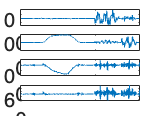

clear; close all; clc;

load('data/data_dynamic_31052025_0944_task_7_b.mat');



acc = meas.acc; % 3xN (m/s^2)
valid_acc = acc(:, ~any(isnan(acc), 1)); % 3 x 560

valid_acc_x = valid_acc(1,:); % x-axis
valid_acc_y = valid_acc(2,:); % y-axis
valid_acc_z = valid_acc(3,:); % z-axis

DataLength = size(valid_acc, 2);
taxis = linspace(1, DataLength, DataLength);

for i = 1:3
    subplot(4, 1, i);
    plot(taxis, valid_acc(i, :)); hold on;
end


acc_total = sqrt(valid_acc_x.^2 + valid_acc_y.^2 + valid_acc_z.^2);
subplot(4, 1, 4);
plot(taxis, acc_total); hold on;